# Deep Learning for Real-Time Top Quark Jet Tagging 

In this Live Script we develop a predictive model, based on deep convolutional neural network (CNN), that discriminates top quark (signal) jets from QCD plain vanilla (background) jets. Besides developing a predictive model, the workflow presented here includes: accessing and preprocessing data, transforming jets to 2D grayscale images, and deployment of the predictive model on FPGA. 

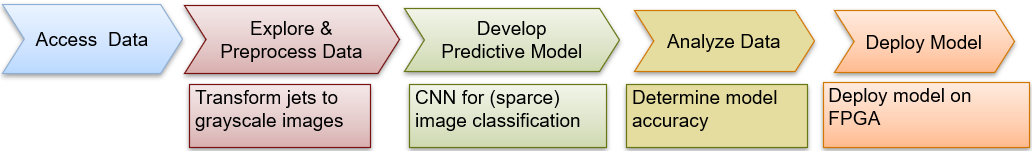

## Introduction

Jets (collimated sprays of particles) are produced in high-energy particle colliders, such as Large Hadron Collider (LHC) at CERN, when protons traveling with near-speed-of-light velocity smash with each other. Protons, during high-energy colissions, 75% of times [*], break into their constituents: quarks and gluons. Quarks and gluons can not be observed individually in detectors, rather they produce narrow cones of ultrarelativistic hadrons and other particles - jets [1]. Fig. 1 shows an example of an event (proton-proton collision) with accompanied 3 jets. Each jet comrpises of its constituents (such as $\pi$, $K$-mesons) as depicted by green lines in Fig. 1. 

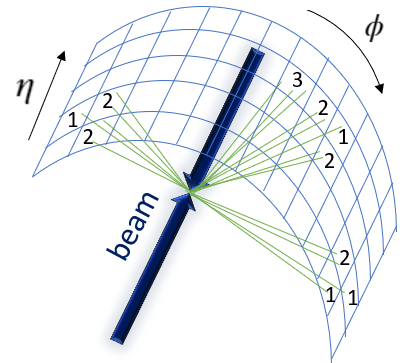

                            Figure1: Particle jets (3 jets are shown) produced during proton-proton collision with their constituents (green lines). Numbers in the cells indicate how many jet constituents scatter in certain direction. These numbers can be used as pixel intensities.

Variables $\eta$ and $\phi$, that uniquely determine positions of calorimeter cell towers on the cylindrical grid surrounding the proton-proton collision (beam) axes, are called pseudorapidity and azimuthal angle respectively. In Fig. 1 three jets are shown, with their constituents, piercing the ($\eta$,$\phi$) rectangular grid.

Variables $\eta$ and $\phi$ are related to the cartesian coordinates of jet constituents' momenta as 

$(1) \quad p_x=p_T \cos \phi, \,\, p_y=p_T \sin \phi, \,\, p_z=p_T\sinh\eta$, 

where transverse momentum $p_T$ is defined as:


$$(2) \quad p_T=\sqrt{p^2_x+p^2_y}=|p|/\cosh \eta.$$


Each jet can contain from a few to tens of constituents and four-momenta of these constituents ($E$, $p_{x}$, $p_{y}$, $p_{z}$) are measured by calorimeter (measuring energy) and particle tracking devices (measuring three momenta). Most jets produced at 14 TeV energy collissions are "boring", as they are produced by well understood mechanisms. They are called background jets. Jets produced from top quarks (top quark is the heaviest elementary particle known to exist as of today, heavier than the Higg's boson) are rare and can contain potentially novel physics. It is important to be able to single out quickly top jets from the overwhelming amount of background jets. This way one can reduce drastically amount of data to be stored and to be analyzed for detecting new physics. To avoid deluge of data, efficient (fast and accurate) real-time data filtering will be crucial for searching for rare events after the high-luminosity upgrade of LHC, where data filtering will be perfmormed by AI algorithms deployed on FPGAs [2]. 

In this Live Script, using deep network designer App, we will build a simple convolutional neural network graphically, without coding. Using CNN we will be able to discriminate top (signal) jets from background jets. We will also show how to deploy trained networks on FPGA. In the first part we will access reference data sets and then we will transform each jet to a 2D grayscale image with 37x37 pixels. In the preprocessing steps and in choosing CNN for jet classification task we will follow existing literature [1,3,4]. 

## Reference Datasets

Datasets are accessed at [Top Quark Tagging Reference Dataset | Zenodo](https://zenodo.org/record/2603256#.YIgG8R-SlaR)[5], where details on the datasets can be found. Jet constituents are already clustered into jets by established particle physics algorithm. Each jet in dataset is recorded as a collection of tens of non-zero 4-momenta (4-momenta of its constituents). For example a jet comprising of 30 constituents has 4*30 nonzero entries: $E_0$, $p_{x0}$, $p_{y0}$, $p_{z0}$,... $E_{29}$, $p_{x29}$, $p_{y29}$, $p_{z29}$. 

- Jets are produced from 14 TeV energy collissions  

-  Jets are in the $p_T$ range [550,650] GeV

- Jets have |$\eta$| < 2, hence scattering in the narrow cones around particle beam direction (small angle scatteirngs) are not captured

- The leading 200 constituent four-momenta of jets are stored, with zero-padding for jets with fewer than 200

- Constituents within each jet are sorted by $p_T$, with the highest $p_T$ first 

- A flag (1 for top, 0 for background) is kept for each jet in a column called "is_signal_new"

To represent jet as an image, the cylindrical coordinates: pseudo-rapidity $\eta$ and azimuth $\phi$ of jet constituents, defined in Eqs. (1) and (2), will play a central role  (which we will calculate from dataset):

- $\eta= \sinh^{-1} \frac{p_z}{p_T}$, pseudo-rapidity

- $\phi=\tan^{-1} \frac{p_y}{p_x}$, azimuthal angle

## Accessing Data

To access data we use python and read part of the training (and test) data as pandas' dataframe. 

`$jupyter lab      `

`>> import pandas as pd`

`>> df=pd.read_hdf('train.h5','table').sample(n=30000)            # read 30k random jets of "table" dataset into pandas' dataframe df`

After this, we export `df` to parquet format to save on disk: 

`>> df.to_`

`parquet('jets30000.parquet.gzip', compression='gzip')   # save in parquet format `

We read parquet file as a MATLAB table in `T_jets` variable.

pyrun("import pandas as pd") 
pyrun("df=pd.read_hdf('train.h5','table').sample(n=30000)")
pyrun("df.to_parquet('jets30000.parquet.gzip', compression='gzip')") 

T_jets=parquetread('jets30000.parquet.gzip')

T_jets = 30000×807 table
     E_0       PX_0       PY_0       PZ_0       E_1       PX_1       PY_1       PZ_1       E_2       PX_2       PY_2       PZ_2       E_3       PX_3       PY_3       PZ_3       E_4       PX_4       PY_4       PZ_4       E_5        PX_5       PY_5       PZ_5       E_6        PX_6       PY_6       PZ_6       E_7        PX_7       PY_7       PZ_7        E_8        PX_8       PY_8 

 As a next step we move `"is_signal_new"` variable as a first column, delete `"index"` column and sort the table by placing all background jets first, then all top jets. 

T_jets = movevars(T_jets,'is_signal_new','Before','index');
T_jets = removevars(T_jets,{'index'})

T_jets = 30000×806 table
    is_signal_new     E_0       PX_0       PY_0       PZ_0       E_1       PX_1       PY_1       PZ_1       E_2       PX_2       PY_2       PZ_2       E_3        PX_3       PY_3       PZ_3       E_4       PX_4       PY_4       PZ_4       E_5       PX_5       PY_5       PZ_5       E_6       PX_6       PY_6       PZ_6       E_7        PX_7        PY_7       PZ_7       E_8       PX_8

T_jets = sortrows(T_jets,'is_signal_new'); 

Next, we calculate how many background and top jets are contained in the table.

G = groupsummary(T_jets,'is_signal_new')  

G = 2×2 table
    is_signal_new    GroupCount
    _____________    __________

          0            14810   
          1            15190   


## Preprocessing Data: Transforming Jets to Grayscale Images  

From each jet we retain only its first 35 constituents and using `Jet_Table_To_Jet_Tensor` function (that is defined at the end of the Live Script) we store jets data in 3D tensor `Jet`. First (row) and second (column) indices of `Jet` run over 35 jet constituents and four momenta of each constituent respectively, as shown in Fig. 2. Third index of `Jet `(enumerating pages of the 3D tensor) runs over different jets from 1 to 30,000. 

Jet=Table_To_3DTensor(T_jets);     % In Jet tensor we store 4 momenta of leading 35 constituents of each jet        

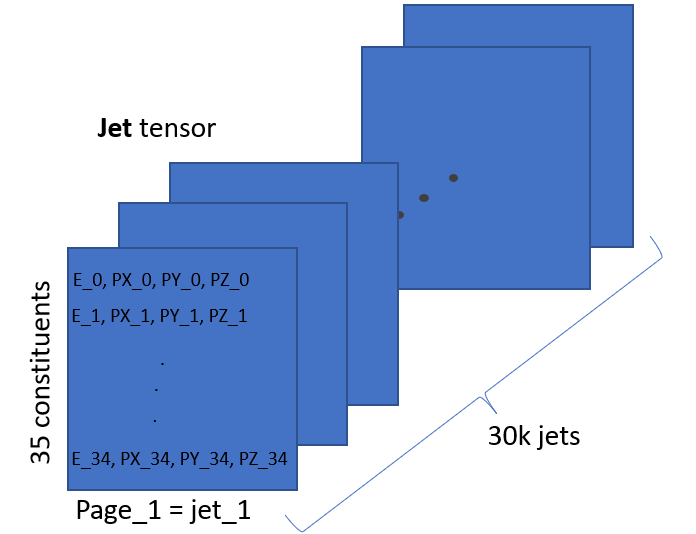

                               Figure 2: Jet tensor.

Next, we assign $\eta$ and $\phi$ coordinates to jet constituents (specify their scattering direction).

pT=sqrt(Jet(:,2,:).^2+Jet(:,3,:).^2);         % transverse momentum of jet constituents
eta=squeeze(asinh(Jet(:,4,:)./pT));           % pseudorapidity tensor eta with 35 rows and 30k columns
phi=squeeze(atan2(Jet(:,3,:),Jet(:,2,:)));    % azimuth tensor phi with 35 rows and 30k columns

We shift $\eta$-s and $\phi$-s of jet's constituents so that the first constituent of each jet (one with the highest value of  $p_T$) has $\eta=\phi=0$.

eta = eta - eta(1,:);        % this and line below: centering the hardest jet constituent in (eta,phi) grid
phi = phi - phi(1,:);        % jet constituent with the largest pT will have eta=phi=0  

To represent jet as an image first we define a pixel of an image as a coarse-grained calorimeter cell. We group together calorimeter cells into $N_b\mathrm{x}N_b$ larger cells, buckets of linear size: $\Delta \eta =\Delta \phi=\frac{3.2}{N_b}$. A single pixel will be ($\Delta$η=$\frac{3.2}{N_b}$,$\Delta$$\phi$=$\frac{3.2}{N_b}$) region in  ($\eta$,$\phi$)  plane.

Nb=37;                                 % number of buckets for eta and phi  
Xedges=linspace(-1.6,1.6,Nb+1);        % edges for buckets for eta. Nb+1 edges means Nb buckets 
Yedges=linspace(-1.6,1.6,Nb+1);        % edges for buckets for phi

### The Simplest Choise for Pixel Intensity

The simplest way to represent a jet as a grayscale image is to use particle count in a pixel (number of jet constituents traveling in the same direction, hence having similar ($\eta, \phi$) coordinates) as a grayscale intensity of that pixel. 

Jet_Image=zeros(Nb,Nb,size(Jet,3));
parfor n = 1:size(Jet,3)
    Jet_Image(:,:,n) = histcounts2(eta(:,n),phi(:,n),Xedges,Yedges);  
end

One can visualize jet # 1300 as

Jet_Image(:,:,1300)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

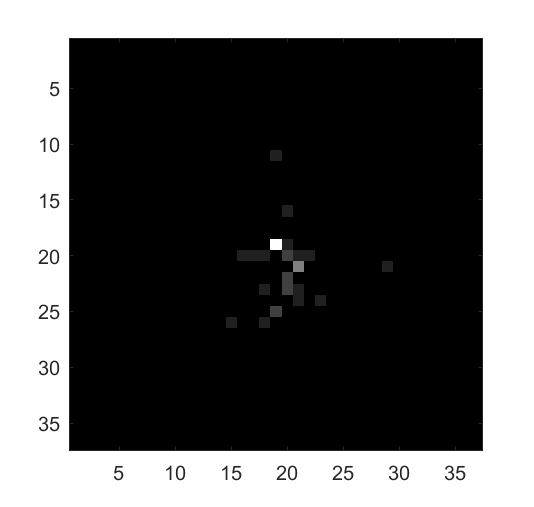

imagesc(Jet_Image(:,:,1300))
colormap(gray);

Nex, to get a better feeling what are main features that discriminate top jets from background jets, we standardize jets, using` zscore `function and plot "average" of all background/ top jet images.

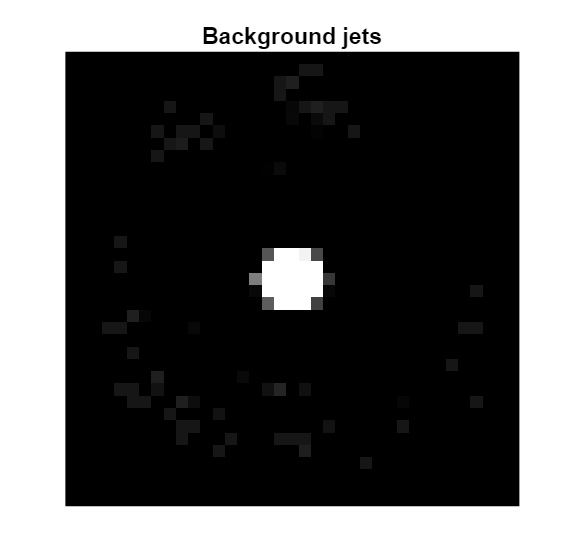

Jet_Image = zscore(Jet_Image,0,3);             % x -> (x-mu)/sigma
I_b_N=sum(Jet_Image(:,:,1:G{1,2}),3)/1000;
I_t_N=sum(Jet_Image(:,:,G{1,2}+1:end),3)/1000;
imshow(I_b_N)
truesize([300, 300]) 
title("Background jets")

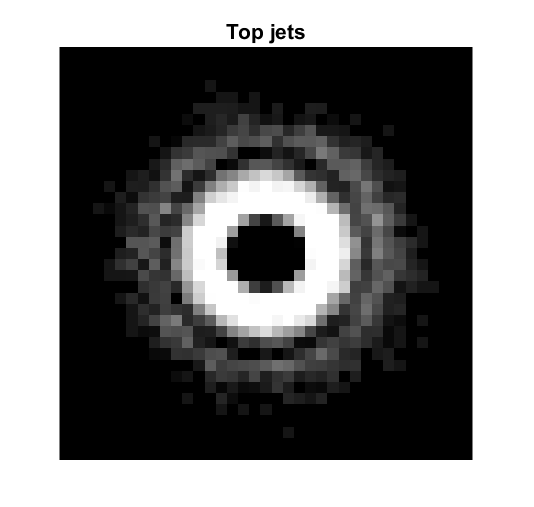

imshow(I_t_N)
truesize([300, 300]) 
title("Top jets")

As we see background jets are focused near the origin, while top jects have doughnut-like distribution. 

After this, one can use obtained grayscale images, save them to disk and apply image classification models that are presented in this section to discriminate top jets from background jets.

### A Better Choice for Pixel Intensity

It turns out that better choice is to use a total transverse momentum of a jet as a pixel intensity. Following [3], we will use summed values of $p_T$-s of a jet constituents in a given pixel, coarse grained ($\Delta$η=$\frac{3.2}{N_b}$,$\Delta$$\phi$=$\frac{3.2}{N_b}$) region, as a grayscale intensity of that pixel. Choosing $p_T$ for grayscale image intensity (instead of, say, energy) and also using coordinates $\eta$ and $\phi$ bring great flexibility during preprocessing. For example shifts in $\eta$-s and $\phi$-s will not change intensities, since $p_T$-s are invariant with respect to $\phi \to    \phi +const$ (rotations in XY plane) and $\eta \to    \eta +const$ (Lorentz boosts along Z, beam, axis).

On Fig. 3 we show distribution of total transverse momenta of background and top jets.

P=squeeze(sum(pT,1));                  % total transverse momentum of a jet
clf;
histogram(P(1:G{1,2}));                % distribution of transverse momenta of background jets
hold on
histogram(P(G{1,2}+1:end));            % distribution of transverse momenta of top jets
title("Jet's histograms")
legend({'Background jets','Top jets'},'Location','best')
xlabel("p_T (GeV)")
ylabel("# of jets")
hold off

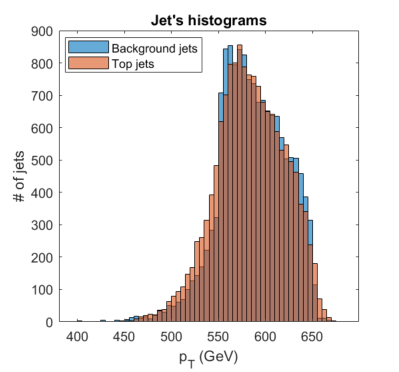

Figure 3: Distribution of tackground and top jets' transverse momenta.

#### Accumulate Transverse Momenta in Buckets

The input image will be a 2D grid where the input layer contains summed transverse momenta of a jet constituents $\sum p_T$ in a particular angular region $(\Delta \eta, \Delta \phi)$. Define a single channel for "color":  gray color intensity of a pixel = summed transverse momenta of jet constituents in a pixel (pixel is a coarse-grained calorimeter cell).

xGrp = discretize(eta,Xedges);    % xGrp is same size as eta: 35x30k. Instead of eta values, xGrp contains bucket numbers for that values of eta
yGrp = discretize(phi,Yedges);    % yGrp is same size as phi: 35x30k. Instead of phi values, yGrp contains bucket numbers for that value of phi
zGrp = repelem(1:size(Jet,3),size(eta,1));       % zGrp is a row vector with 35*30k elements: 1,1,1..., 2,2,2..., 30k,30k,30k... 
V = rmmissing([pT(:) xGrp(:) yGrp(:) zGrp(:)]);  % remove rows with missing entries from a matrix V with 4 columns 
I = accumarray(V(:,2:4), V(:,1), [Nb, Nb, size(Jet,3)]);

`B ``= accumarray(ind,data,sz) `sums groups of data by accumulating elements of a vector `data` according to the groups specified in `ind`. 

Next 2 steps of preprocessing are: 

- Put maximum intensity pixel in the center of each page of $I$.

- Normalize: Scale the pixel intensities such that  $\sum^{37}_{i,j=1}  I_{ij} = 1$ in the image, where $i$ and $j$ indices run over the pixels.  

Ia=zeros(Nb^2,size(Jet,3));
parfor n=1:size(Jet,3)
    Ia(:,n)=reshape(I(:,:,n),Nb^2,1);
    Ia(:,n)=circshift(Ia(:,n),ceil(length(Ia(:,n))/2)-find(Ia(:,n)==max(Ia(:,n)))); % maximum of I will be centered       
end
Ia=normalize(Ia,'norm');            % normalize each column of Ia
I=reshape(Ia,Nb,Nb,[]);

We visualize jets after centering hardest object and normalization. We average all background jet images together in a single image, similarly all top jets.

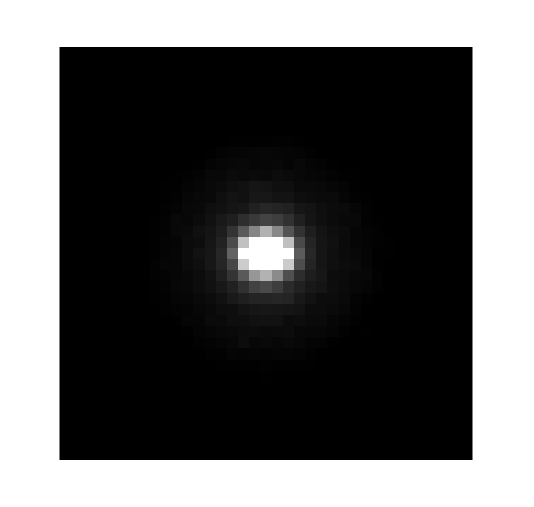

I_b=sum(I(:,:,1:G{1,2}),3)/200;      % sum all background jets
I_t=sum(I(:,:,G{1,2}+1:end),3)/200;  % sum all top jets
imshow(I_b)
truesize([300, 300]) 

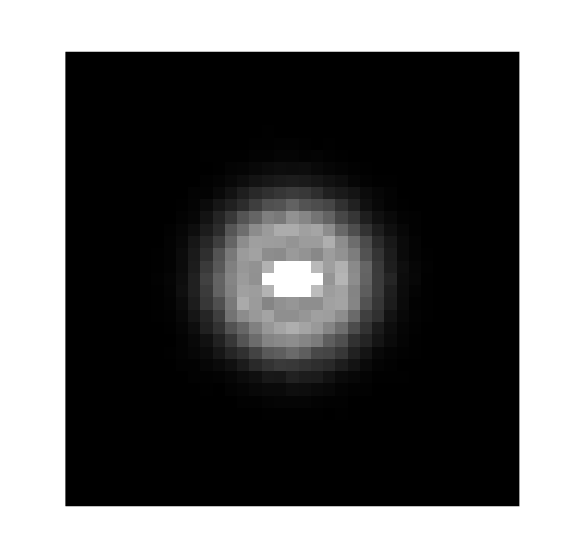

imshow(I_t)
truesize([300, 300]) 

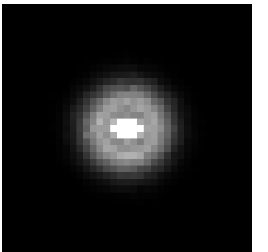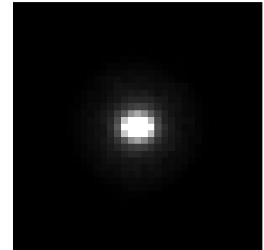

Figure 4: Averaged (left) top jets and (right) background jets before standardization.

As we can see in Fig. 4 that top jets have pronounced halo-like structure, whereas background jets are more focused near the center. The standardization step ($x \to \frac{x-\mu}{\sigma}$), that we will perform next using `zscore `function, turns out to be very efficient to visualize better distinction between averaged background and top jet images. 

Standardization step:

- Zero-center: Subtract the mean $\mu_{ij}$ of the normalized training images from each image, $I_{ij} \to  I_{ij} - \mu_{ij}$ .

- Standardize: Divide each pixel value by the standard deviation $\sigma _{ij}$ of that pixel value in the normalized training dataset, $I_{ij} \to  I_{ij}/\sigma_{ij}$.

I = zscore(I,0,3);                  % x -> (x-mu)/sigma

Let's visualize background and top jets after standardization.

I_b=sum(I(:,:,1:G{1,2}),3)/200;
I_t=sum(I(:,:,G{1,2}+1:end),3)/200;
imshow(I_b)
truesize([300, 300]) 
imshow(I_t)
truesize([300, 300]) 

As seen in Fig. 5, standardization step made top jet images visually more distinct from background jet images. Top jet images average in a donut-like shape distribution, while background images are centered near origin (the hardest object). We note that standardization step does not affect classification accuracy and is mainly for better visualization of distinction between background and top jet images.  

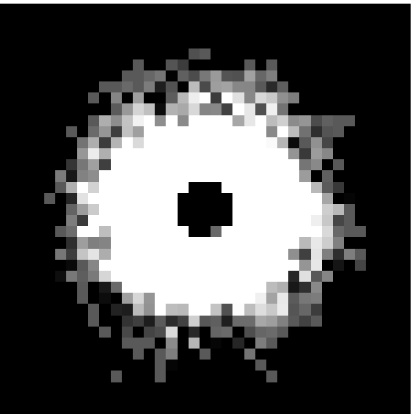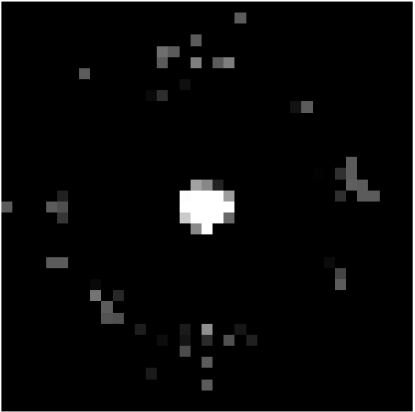

Figure 5: Averaged (left) top jets and (right) background jets after standardization.

**Comparing visually alternative choices for grayscale image pixel intensity**

Visual inspection of (sparse) images in Fig. 6 shows us a clear correlation between the two images obtained for two different choices of pixel intensities (transverse momentum and particle count). Classification accuracy of predictive model (for simple deep learning architecture that we will present below) is higher (by ~5%) when using transverse momenta for pixel intensity as compared to the case when using a particle count as pixel intensity. 

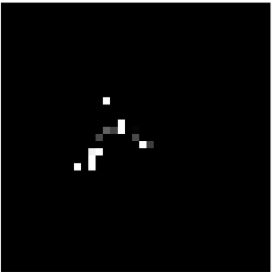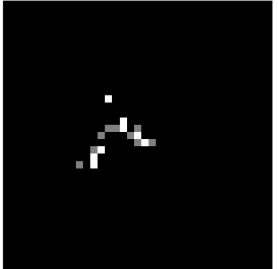

Figure 6: Representation of a jet as an image when using (left) transverse momentum or (right) particle count as pixel intensity.

In the literature multichannel color images are used as an input layer [4]. They are shown to improve jet calssification accuracy over the single channel grayscale images that we have adopted for simplicity here. 

## Save Images

Finally, save images to disc.

currentFolder = pwd;
folder1=[currentFolder filesep 'JetLabels' filesep 'Background'];
folder2=[currentFolder filesep 'JetLabels' filesep 'TopJets'];

g=min(G{1,2},G{2,2});    % there are G{1,2} background and G{2,2} top jets
parfor aa=1:g            % we keep same number of background and top jets
    imwrite(I(:,:,aa), fullfile(folder1,['jet', sprintf('%d',aa),'.png']));
    imwrite(I(:,:,aa+g), fullfile(folder2,['jet', sprintf('%d',aa),'.png']));
end

## Develop a Predictive Model 

We will develop a simple deep learning predictive model based on convolutional neural network, following [4]. The independence from prior knowledge and expert intervention in feature extraction is a major advantage of deep learning. CNNs, also known as shift invariant networks, are powerful neural network architectures particularly efficient for image classification tasks. They learn to optimize their filters through automated learning. 

**Create Deep Learning Network Architecture**

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variablNumber of le `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 30-Apr-2021 16:24:37

### Create Convolutional Neural Network

layers = [
    imageInputLayer([37 37 1],"Name","imageinput","Normalization","none")
    convolution2dLayer([4 4],64,"Name","conv_1","Padding","same","Stride",[2 2],"WeightLearnRateFactor",0.1)
    reluLayer("Name","relu1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([4 4],64,"Name","conv_2","Padding","same","Stride",[2 2],"WeightLearnRateFactor",0.1)
    reluLayer("Name","relu2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([4 4],64,"Name","conv_3","Padding","same","Stride",[2 2],"WeightLearnRateFactor",0.1)
    reluLayer("Name","relu3")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(2,"Name","fc","WeightLearnRateFactor",0.1)
    reluLayer("Name","relu4")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

**Plot Layers**

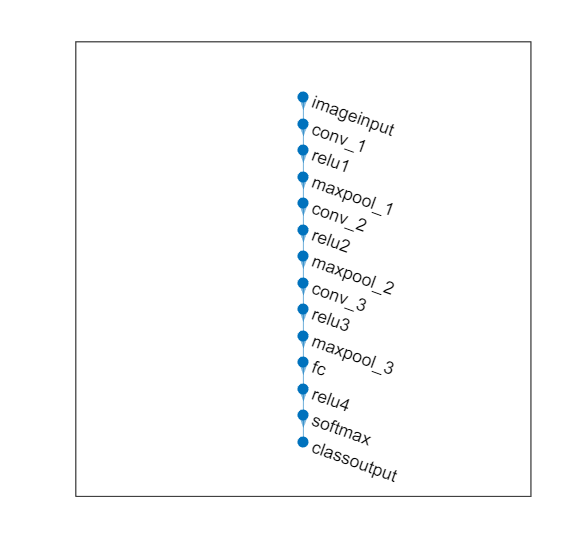

plot(layerGraph(layers));

% deepNetworkDesigner                 % open App and import the above network from the workspace
% rng(0)     % rng default            % before training network set random seed for reproducibility 

For training the network (within the Deep Network Designer app) from the training data (~30k images, with 50% background and 50% top jets) we allocated 20% to the validation set and stopped training when noticed performance has plateaued.

Network architecture is sketched in the left column of Fig. 7. 

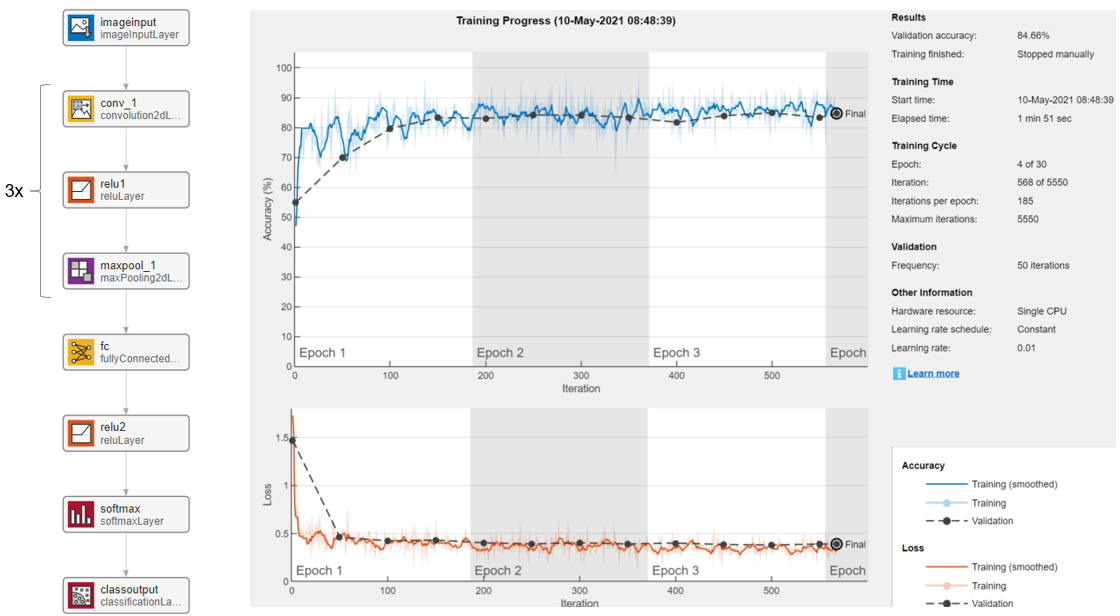

Figure 7: Left column: network architectrue. Right side: training progress and results.

First layer of our network is an image input layer. Second layer is a convolutional layer with 64 filters, followed by relu (a commonly used nonlinear activation function) and maxpooling layers.  Pooling layers in general perform downsampling, by sending only the important data to the next layers in the CNNs, hence reducing the amount of computations. Maxpooling layers that we use have 2x2 filters and stride 2 and work as sketched below in Fig. 8.

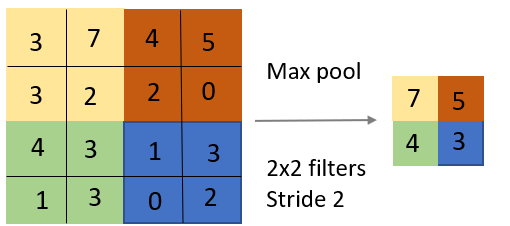

Figure 8: Illustration of how maxpooling layers work. 

Then comes fully connected layer with output size 2, followed by its relu and finally output layer preceeded by normalization softmax layer (normalizing numbers to probabilities).

With just 1 convolutional layer (followed by its relu and maxpooling layers) we have reached classification accuracy of over 82% on test (unseen during training phase) data (10k jet images, with 50% top jets). When using 3 identical convolutional layers, with their corresponding relu and maxpooling layers, as sketched in the left column of Fig. 7 and as included in the code section, we reached ~85% classification accuracy on test (unseen) dataset. Confusion matrix chart in Fig. 9 shows that this particular network is more likely to classify correctly top jets, than the background jets.

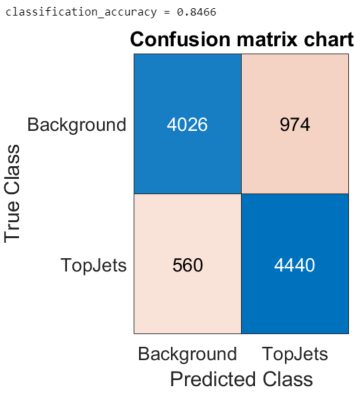

Figure 9: Confusion matrix chart.

Below we apply our trained network to unseen test data of 10k jets. 

% export trained network to the workspace from deepNetworkDesigner 
% save('trainedNetwork_JetTaggingCNN.mat','trainedNetwork_1') % save with different name
%
% load trainedNetwork_Best.mat        % trained network will be loaded in a workspace variable: trainedNetwork_1

currentFolder = pwd;
testimageFolder=[currentFolder filesep 'TestImagesFolder'];
imds = imageDatastore(testimageFolder,'IncludeSubfolders',true,'FileExtensions','.png','LabelSource','foldernames');

labels_predicted=categorical(repmat( "Background",1,1e4));
scores=zeros(1e4,2);

parfor jj=1:1e4    
    [labels_predicted(jj),scores(jj,:)]=classify(trainedNetwork_1, readimage(imds,jj));  %.png file is read as 37×37 uint8 matrix
end

labels_true=categorical([repmat( "Background",1,5e3), repmat( "TopJets",1,5e3)]);
C = confusionmat(labels_true,labels_predicted);
classification_accuracy=trace(C)/sum(sum(C))

classification_accuracy = 0.8201

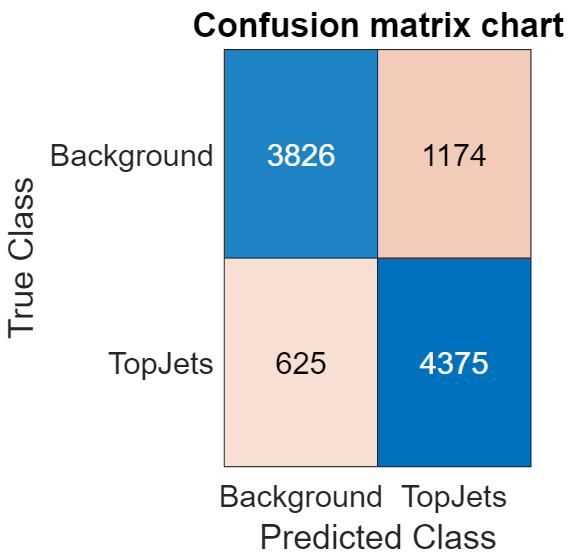

confusionchart(labels_true,labels_predicted, "title","Confusion matrix chart",'fontsize',14);

`imageDatastore` object manages a collection of image files, where each individual image fits in memory, but the entire collection of images does not necessarily fit. It is especially useful when working with big data.  

By `perfcurve `function we can calculte the false positive rate (specificity X), the true positive rate (sensitivity Y), ROC curve and area under curve (AUC). These are shown in Fig. 10. 

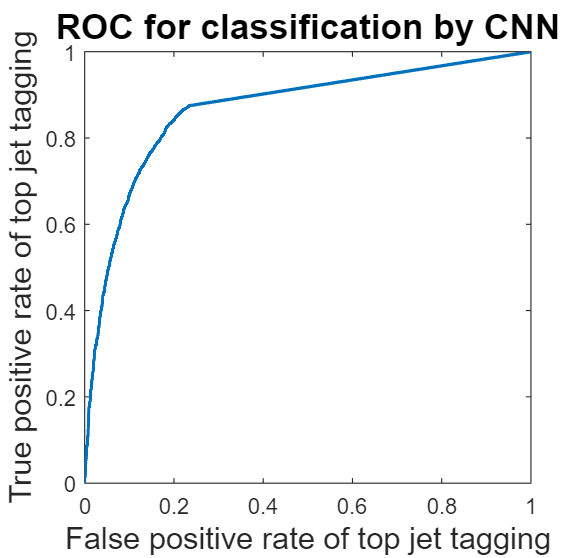

[X,Y,~,AUC] = perfcurve(double(labels_true),scores(:,2),2);
plot(X,Y)
xlabel('False positive rate of top jet tagging','fontsize',14); 
ylabel('True positive rate of top jet tagging','fontsize',14);
title('ROC for classification by CNN','fontsize',16)

AUC  % calculate area undre the curve

AUC = 0.8676

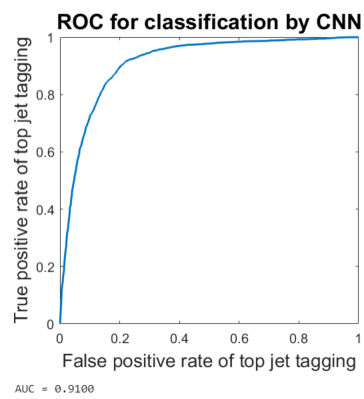

Figure 10: ROC curve.

Finally we note that using more complex deep networks (with no finetuning of network parameters), such as resnet18, has incresed classification accuracy by ~1%, however time to classify a single jet increased by a factor of ~3. For training more complex deep networks, use of a GPU is convenient, as it accelerates training phase considerably. MATLAB automatically detects when GPU is connected and starts training on GPU when it is available. For example a single GPU (TITAN Xp with 3840 CUDA Cores) takes ~ half a minute per epoch to train resnet18 network on 30k training images, whereas CPU takes ~6 minutes per epoch (GPU brings 12x acceleration of training phase). The true advantage of using GPU shows up when tunning hyperparameters of the network and when dealing with big data.

## Deploy Trained Network on FPGA

In the final section of Livescript we [deploy trained network to accelerated hardware](https://www.mathworks.com/help/deep-learning-hdl/ug/image-category-classification-using-deep-learning.html).

One needs to install: Deep Learning HDL Toolbox and [Deep Learning HDL Toolbox Support Package for Xilinx FPGA and SoC Devices](https://www.mathworks.com/help/releases/R2021a/supportpkg/xilinxdeeplearning/ug/install-support-package-for-xilinx-fpga-soc.html). 

**Create Target Object**

Use the `dlhdl.Target` class to create a target object with a custom name for your target device and an interface to connect your target device to the host computer. Interface options are JTAG and Ethernet. To use JTAG,Install Xilinx™ Vivado™ Design Suite 2019.2. To set the Xilinx Vivado toolpath, enter:

hTarget = dlhdl.Target('Xilinx','Interface','Ethernet');

**Create WorkFlow Object**

Use the `dlhdl.Workflow` class to create an object. When you create the object, specify the network and the bitstream name. Specify the saved pretrained alexnet neural network as the network. Make sure that the bitstream name matches the data type and the FPGA board that you are targeting. In this example, the target FPGA board is the Xilinx ZCU102 SoC board. The bitstream uses a single data type.

hW=dlhdl.Workflow('Network',trainedNetwork_1,  'Bitstream', 'zcu102_single','Target',hTarget);

**Compile the network**

To compile the network, run the compile method of the dlhdl.Workflow object. You can optionally specify the maximum number of input frames.

dn = hW.compile('InputFrameNumberLimit',15)

### Compiling network for Deep Learning FPGA prototyping ...
### Targeting FPGA bitstream zcu102_single.
### The network includes the following layers:
     1   'imageinput'    Image Input             37×37×1 images                                                (SW Layer)
     2   'conv_1'        Convolution             64 4×4×1 convolutions with stride [2  2] and padding 'same'   (HW Layer)
     3   'relu1'         ReLU                    ReLU                                                          (HW Layer)
     4   'maxpool_1'     Max Pooling             2×2 max pooling with stride [2  2] and padding 'same'         (HW Layer)
     5   'conv_2'        Convolution             64 4×4×64 convolutions with stride [2  2] and padding 'same'  (HW Layer)
     6   'relu2'         ReLU                    ReLU                                                          (HW Layer)
     7   'maxpool_2'     Max Pooling             2×2 max pooling with stride [2  2] and padding 'same'         (HW L

dn = struct with fields:
             weights: [1×1 struct]
        instructions: [1×1 struct]
           registers: [1×1 struct]
    syncInstructions: [1×1 struct]


**Program Bitstream onto FPGA and Download Network Weights**

To deploy the network on the Xilinx ZCU102 hardware, run the deploy function of the `dlhdl.Workflow` object. This function uses the output of the compile function to program the FPGA board by using the programming file. It also downloads the network weights and biases. The deploy function starts programming the FPGA device, displays progress messages, and the time it takes to deploy the network.

% hW.deploy

Network deployed on FPGA accelerates classification time by >15x. Converting single precision to fixed-point, using the [Deep Learning Toolbox Model Quantization Library](https://www.mathworks.com/matlabcentral/fileexchange/74614-deep-learning-toolbox-model-quantization-library) and [Deep Network Quantizer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkquantizer-app.html) app, can further accelerate classification time by a factor of >3.3x.  

## References

[*] 25% of high-energy proton-proton collisions are elastic ones, where the protons remain intact but emerge on slightly altered paths  (deviating by a millimetre over a distance of 200 m), mediated by pomerons (a colour-neutral virtual glueball made up of an even number of gluons) and [recently dsicovered odderons](https://cerncourier.com/a/odderon-discovered/) 

[1] Mathew D. Schwartz, *Modern Machine Learning and Particle Physics*,[ arXiv: 2103.12226](https://arxiv.org/pdf/2103.12226.pdf)

[2] K. Albertsson, et al., *Machine Learning in High Energy Physics Community White Paper, *[arXiv: 1807.02876](https://arxiv.org/abs/1807.02876)

[3] L. de Oliveira, M. Kagan, L. Mackey, B. Nachman and A. Schwartzman, *Jet-images — Deep learning edition*, [Journal of High Enerpgy Physics](https://inspirehep.net/literature/1405106) (2016) 

[4] P. T. Komiske, E. M. Metodiev, and M. D. Schwartz, *Deep learning in color: towards automated quark/gluon jet discrimination*, [Journal of High Energy Physics](https://link.springer.com/article/10.1007/JHEP01(2017)110) (2017)

[5] Kasieczka, Gregor, Plehn, Tilman, Thompson, Jennifer, & Russel, Michael. (2019). Top Quark Tagging Reference Dataset (v0 (2018_03_27)) [Data set]. Zenodo. https://doi.org/10.5281/zenodo.2603256

function y= Table_To_3DTensor(x)
    y = x{:,2:4*35+1}';                
    y = reshape(y,4,35,[]);              
    y = pagetranspose(y);
end